cd 'E:\OneDrive\学习\大四下spring 2021\Advance Control Lab\Advance-Control-Lab\Preparatory Work 4'
clear
clc


s=tf('s'); Py=(100)/(s*(s+100)); Ptheta=-10/pi*(50*s^2)/(s^2+0.49*s+50);
C=(40*s+179)/s;
TF=feedback(C*Py,1)*Ptheta

TF =
 
                 -6.366e05 s^3 - 2.849e06 s^2
  ----------------------------------------------------------
  s^5 + 100.5 s^4 + 4099 s^3 + 24860 s^2 + 208771 s + 895000
 
Continuous-time transfer function.



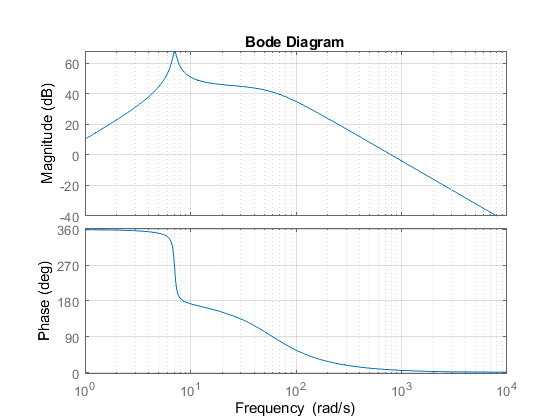

bode(TF); grid on;

[MAG,PHASE,W]=bode(TF);
Max_index=find(MAG==max(MAG));
Mag_max=mag2db(MAG(Max_index))

Mag_max = 67.9384

W_max=W(Max_index)

W_max = 7.0626

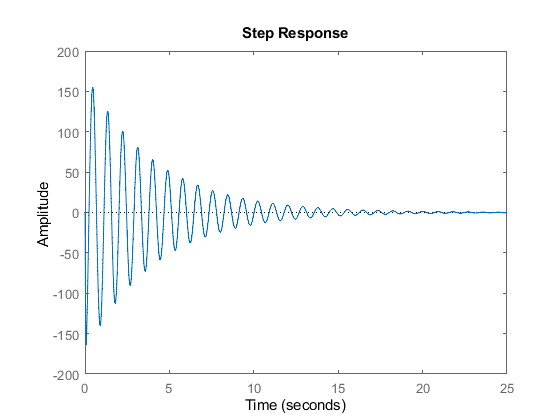



step(TF)


Ctheta=-2*(1+0.12*1/s);